# Test CNN2D optimization, training and Testing

## Load the Szenario or build from scratch

clearvars;
%LoadToolbox
addPaths;

%DataLocation
locationData = 'Data\';

loadStruct = [];
%Struct DataLocation
loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat'])];
loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat'])];
loadStruct.targetGas = 'acetone';

% If multiple Sensors should be used
%loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat']);convertCharsToStrings([locationData 'sensorB.mat'])];
%loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat']);convertCharsToStrings([locationData 'target.mat'])];

%Used Method %see LoadDataFull 1: 70% 10% 20% Split
loadStruct.loadMethod = 1;

%Expected Input Dimensions
loadStruct.dataSize = [4,1440];

%Expected Output Dimensions
loadStruct.Outputsize = 1;

%Specify Regression or Classification
loadStruct.Regression = true;


%SaveFlag = 
loadStruct.saveFlag = true;

%Random Flag; False: Reproduzable random Samples; True: in every execution Random
loadStruct.randomFlag = false;

%NormalizeInput 
loadStruct.normFlag = true;

loadStruct.OcclusionFlag = false;

loadStruct.saveName = [locationData 'Szenario_SA_1_Acetone.mat'];

%Not the exact split is performed than in the original data (~20 UGMs less in test Set)
[data,target] = loadDataFull(loadStruct);

Data\sensorA.mat
acetone
Split
RandomFlag
   0



## Optimize, Train and Test TCOCNN

%Generate Model without optim hyperparameter
tcocnnTest = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression);

No Model Built


|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |     n_filter | SectionDepth | InitialLearn-|       stride |       kernel |   numNeurons |      dropOut |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | Rate         |              |              |              |              |
|================================================================================================================================================================================|
|    1 | Best   |      16.669 |       83.45 |      16.669 |      16.669 |          102 |            4 |   0.00065945 |           21 |           34 |          872 |      0.25696 |
|    2 | Accept |      18.144 |      117.55 |      16.669 |      16.754 |          147 |            3 |  

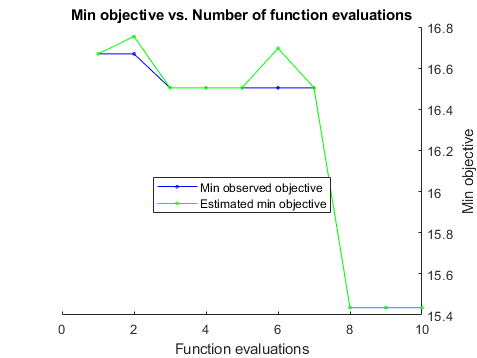


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 10 reached.
Total function evaluations: 10
Total elapsed time: 890.9151 seconds
Total objective function evaluation time: 889.4424

Best observed feasible point:
    n_filter    SectionDepth    InitialLearnRate    stride    kernel    numNeurons    dropOut
    ________    ____________    ________________    ______    ______    __________    _______

       65            4             0.00067118         31        76         1032       0.44424

Observed objective function value = 15.436
Estimated objective function value = 15.4366
Function evaluation time = 81.0527

Best estimated feasible point (according to models):
    n_filter



%If no set of params is availabel Optimization can be done this way
paraStore = [locationData 'acetoneParams.mat'];
tcocnnTest.optimizeTCOCNN(paraStore,data,target,10)


%After optimization train the model with optizied hyperparameter
tcocnnTest.train(data.train,target.train);

%Predict Test Data
pred = tcocnnTest.apply(data.test);
disp(helpers.RMSE.loss(pred,target.test));

   17.7347



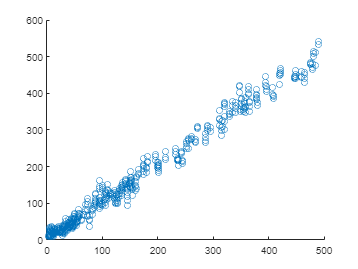


%display target vs pred
figure()
scatter(target.test,pred)

## If alredy Optimized -> Train and Test TCOCNN

%Generate Model without optim hyperparameter
paraStore = [locationData 'acetoneParams.mat'];
load(paraStore);
tcocnnTest2 = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression,optim);


%With already optimized variables start training directly
tcocnnTest2.train(data.train,target.train);
%Predict Test Data
pred = tcocnnTest2.apply(data.test);
disp(helpers.RMSE.loss(pred,target.test));

   16.8216



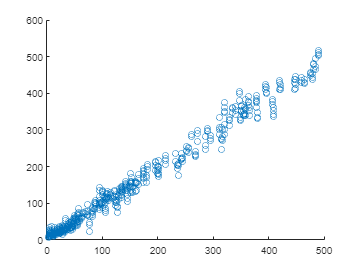


%display target vs pred
figure()
scatter(target.test,pred)